# 2リンクマニピュレータのMATLAB Functionブロックのエクスポート

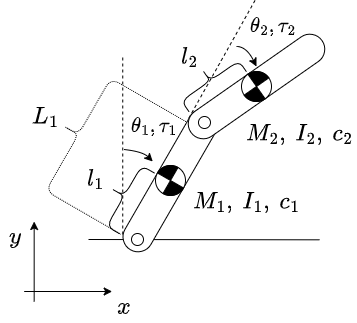

重心と回転軸の間の距離をl、関節の長さをLと分けている。

重心周りの慣性モーメントI、各関節の減衰係数c。

オリジナルは↓

https://www2.kaiyodai.ac.jp/~shimizu/lec/b/rb-2/rb-2.pdf

clear;
syms M_1 M_2 L_1 l_1 l_2 g I_1 I_2 c_1 c_2 real % 物理パラメータ 実数値しかとらないので念のためreal
syms theta [2 1]
syms dtheta [2 1] 
syms ddtheta [2 1] 
syms tau [2 1]

%--- 一般化座標qの定義 ---
q = theta;
dq = dtheta;
ddq = ddtheta;

%--- 座標の定義と、それらの導関数の記述 ---
x_1 = l_1 * sin(q(1));
y_1 = l_1 * cos(q(1));

x_2 = L_1 * sin(q(1)) + l_2 * sin(q(1)+q(2));
y_2 = L_1 * cos(q(1)) + l_2 * cos(q(1)+q(2));

dx_1 = diff(x_1, q(1))*dq(1) + diff(x_1, q(2))*dq(2);
dx_2 = diff(x_2, q(1))*dq(1) + diff(x_2, q(2))*dq(2);

dy_1 = diff(y_1, q(1))*dq(1) + diff(y_1, q(2))*dq(2);
dy_2 = diff(y_2, q(1))*dq(1) + diff(y_2, q(2))*dq(2);


%--- Lagrange関数の記述 ---
K1 = 1/2*M_1*dx_1^2 + 1/2*M_1*dy_1^2;
K2 = 1/2*M_2*dx_2^2 + 1/2*M_2*dy_2^2;

Krot = 1/2*I_1*dq(1)^2 + 1/2*I_2*(dq(1)+dq(2))^2;

U1 = M_1*g*l_1*cos(q(1));
U2 = M_2*g*L_1*cos(q(1))+M_2*g*l_2*cos(q(1)+q(2));

L = (K1+K2+Krot) - (U1+U2);

D = [c_1*dq(1), c_2*dq(2)]; % 散逸項はあらかじめ微分してある

%--- Lagrange方程式による運動方程式導出---
N = length(q);
for i = 1:N
    dLq(i) = diff(L, dq(i));

    temp = 0;
    for j = 1:N
        temp = temp + diff(dLq(i),dq(j))*ddq(j) + diff(dLq(i),q(j))*dq(j);
    end
    ddLq(i) = temp;

    eq(i) = ddLq(i) - diff(L,q(i)) == -D(i)  + tau(i);
end
eq(1) % 得られた運動方程式の表示

$$ans = \begin{array}{l} {\mathrm{ddtheta}}_{1}\,\left(I_{1}+I_{2}+M_{2}\,{\sigma_{2}}^{2}+M_{2}\,{\sigma_{1}}^{2}+M_{1}\,{l_{1}}^{2}\,{\cos\left(\theta_{1}\right)}^{2}+M_{1}\,{l_{1}}^{2}\,{\sin\left(\theta_{1}\right)}^{2}\right)+{\mathrm{dtheta}}_{2}\,\left(M_{2}\,\left({\mathrm{dtheta}}_{1}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{4}\right)\,\sigma_{1}-M_{2}\,\left({\mathrm{dtheta}}_{1}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+\sigma_{3}\right)\,\sigma_{2}-M_{2}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\left({\mathrm{dtheta}}_{1}\,\sigma_{2}+\sigma_{4}\right)+M_{2}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\left({\mathrm{dtheta}}_{1}\,\sigma_{1}+\sigma_{3}\right)\right)+{\mathrm{ddtheta}}_{2}\,\left(I_{2}+M_{2}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+M_{2}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}\right)-M_{2}\,g\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)-L_{1}\,M_{2}\,g\,\sin\left(\theta_{1}\right)-M_{1}\,g\,l_{1}\,\sin\left(\theta_{1}\right)=\tau_{1}-c_{1}\,{\mathrm{dtheta}}_{1}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)\\ \sigma_{2}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{3}={\mathrm{dtheta}}_{2}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{4}={\mathrm{dtheta}}_{2}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

eq(2) % 得られた運動方程式の表示

$$ans = \begin{array}{l} {\mathrm{ddtheta}}_{2}\,\left(M_{2}\,{l_{2}}^{2}\,{\cos\left(\theta_{1}+\theta_{2}\right)}^{2}+M_{2}\,{l_{2}}^{2}\,{\sin\left(\theta_{1}+\theta_{2}\right)}^{2}+I_{2}\right)-{\mathrm{dtheta}}_{2}\,\left(M_{2}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\left({\mathrm{dtheta}}_{1}\,\sigma_{2}+\sigma_{6}\right)-M_{2}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\left({\mathrm{dtheta}}_{1}\,\sigma_{1}+\sigma_{5}\right)-M_{2}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{4}+M_{2}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{3}\right)+{\mathrm{ddtheta}}_{1}\,\left(I_{2}+M_{2}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)\,\sigma_{2}+M_{2}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\,\sigma_{1}\right)+M_{2}\,\sigma_{3}\,\left({\mathrm{dtheta}}_{1}\,\sigma_{2}+\sigma_{6}\right)-M_{2}\,\sigma_{4}\,\left({\mathrm{dtheta}}_{1}\,\sigma_{1}+\sigma_{5}\right)-M_{2}\,g\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)=\tau_{2}-c_{2}\,{\mathrm{dtheta}}_{2}\\ \mathrm{where}\\ \sigma_{1}=l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\sin\left(\theta_{1}\right)\\ \sigma_{2}=l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+L_{1}\,\cos\left(\theta_{1}\right)\\ \sigma_{3}={\mathrm{dtheta}}_{1}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)+\sigma_{5}\\ \sigma_{4}={\mathrm{dtheta}}_{1}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right)+\sigma_{6}\\ \sigma_{5}={\mathrm{dtheta}}_{2}\,l_{2}\,\sin\left(\theta_{1}+\theta_{2}\right)\\ \sigma_{6}={\mathrm{dtheta}}_{2}\,l_{2}\,\cos\left(\theta_{1}+\theta_{2}\right) \end{array}$$

## MATLAB Function ブロックとしてエクスポート

try % モデルが存在しなければ新規作成。すでにあればそれを開く
    new_system('test_system') 
catch ME
    open_system('test_system')
end

eqns = [eq(1),eq(2)];
S = solve(eqns,ddtheta1,ddtheta2); % 代数方程式として、thetaの2階微分について解く

matlabFunctionBlock('test_system/DualPendulum1', S.ddtheta1,... % theta1の2階微分を出力する演算ブロック作成
     'vars',[I_1 I_2 L_1 M_1 M_2 c_1 c_2 g l_1 l_2 tau1 tau2 theta1 theta2 dtheta1 dtheta2],'outputs',{'ddtheta1'}) % 入力端子順序と出力端子名前を指示
matlabFunctionBlock('test_system/DualPendulum2', S.ddtheta2,... % theta2の2階微分を出力する演算ブロック作成
     'vars',[I_1 I_2 L_1 M_1 M_2 c_1 c_2 g l_1 l_2 tau1 tau2 theta1 theta2 dtheta1 dtheta2],'outputs',{'ddtheta2'}) % 入力端子順序と出力端子名前を指示

## パラメータのセット (ここでやらなくても可)

% 物理パラメータ
M1 = 1;%[kg]
M2 = 1;%[kg]
l1 = 0.5;%[m]
l2 = 0.5;%[m]
L1 = 1;%[m]
g = 9.8;
c1 = 0.5;%減衰 
c2 = 0.5;%減衰 

I1 = M1*l1^2;
I2 = M2*l2^2;

M_0 = [I1+I2+M1*l1^2+M2*L1^2+M2*l2^2 I2+M2*l2^2; I2+M2*l2^2 I2+M2*l2^2]; % 慣性行列 cos(theta2)によらない部分
M_cth2 = [2*M2*L1*l2 M2*L1*l2; M2*L1*l2 0]; % 慣性行列 cos(theta2)がかかる部分

theta1_ini = pi/4; dtheta1_ini = 0; % theta1 初期状態
theta2_ini = 0; dtheta2_ini = 0;    % theta2 初期状態